client = nominal.Client.connect();

% --- find an asset, or create one ---------------------------------------
asset = client.getOrCreateAsset("matlab test asset");

% --- a dataset under it -------------------------------------------------
% The second argument is the reference name, unique among the asset's
% data sources.
dataset = asset.getOrCreateDataset("Dataset for matlab test asset", "default");

% --- declare units before any data exists -------------------------------
% Optional, but it means the first plot comes out labeled. Units are UCUM
% symbols: "Cel" not "C", "1/min" not "rpm".
dataset.setChannelMetadata("rpm", "double", Unit="1/min");

% --- upload a matrix ----------------------------------------------------
% One column per channel, in the same order as the names.
rows = 500;
t = datetime("now", TimeZone="UTC") - seconds(rows/1000) ...
    + milliseconds(0:rows-1)';
v = [1500 + 10*sin(linspace(0, 6*pi, rows))', ...   % rpm
     700  + (1:rows)' * 0.1, ...                    % egt
     30   + (1:rows)' * 0.05];                      % psi

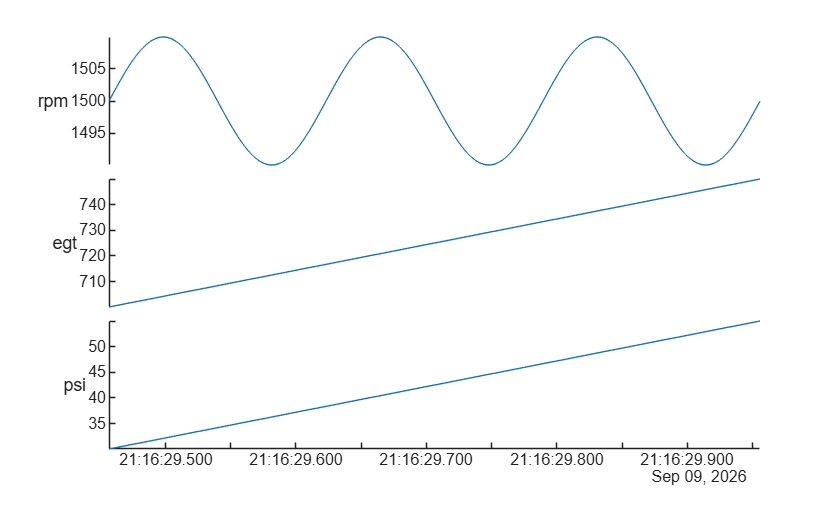

% Eyeball it before it leaves the machine. One panel per channel, because
% the three do not share a scale.
stackedplot(t, v, DisplayLabels=["rpm" "egt" "psi"])

% Write to Nominal
dataset.write(["rpm" "egt" "psi"], t, v);

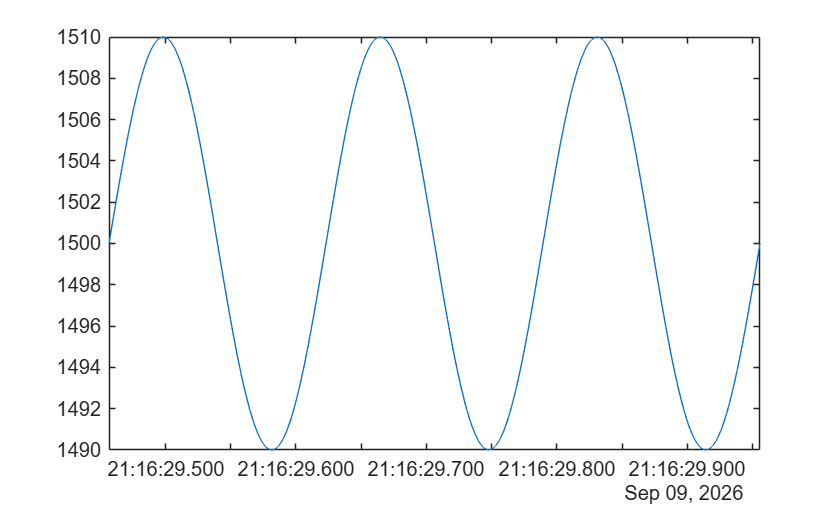

% --- read it back -------------------------------------------------------
% fetch returns a timetable, so it plots, resamples and synchronizes with
% no conversion.
back = dataset.fetch("rpm", t(1) - seconds(1), t(end) + seconds(1));
plot(back.Time, back.("rpm"))

% --- SQL, if you want rows rather than a channel ------------------------
% points_double holds every point this dataset has ever taken, so bound the
% query to the window just written or you get whatever sorts first — old
% rows from earlier runs. In the warehouse ts is a timestamp column, not the
% int64 nanoseconds it comes back as, so the bounds go in as literals. The
% millisecond of slack covers the format truncating rather than rounding.
lo = string(t(1)   - milliseconds(1), "yyyy-MM-dd HH:mm:ss.SSS");
hi = string(t(end) + milliseconds(1), "yyyy-MM-dd HH:mm:ss.SSS");

rowsOut = client.query( ...
    "SELECT ts, channel, value FROM points_double " + ...
    "WHERE dataset_rid = '" + dataset.Rid + "' " + ...
    "AND ts BETWEEN TIMESTAMP '" + lo + "' AND TIMESTAMP '" + hi + "' " + ...
    "ORDER BY ts LIMIT " + 3*rows);   % three channels, rows apiece

% Timestamps arrive as int64 nanoseconds. Convert them and the table reads
% as it stands.
rowsOut.ts = nominal.fromNanos(rowsOut.ts);
disp(head(rowsOut))

             ts             channel    value 
    ____________________    _______    ______

    09-Sep-2026 21:16:29     "egt"      700.1
    09-Sep-2026 21:16:29     "psi"      30.05
    09-Sep-2026 21:16:29     "rpm"       1500
    09-Sep-2026 21:16:29     "egt"      700.2
    09-Sep-2026 21:16:29     "psi"       30.1
    09-Sep-2026 21:16:29     "rpm"     1500.4
    09-Sep-2026 21:16:29     "egt"      700.3
    09-Sep-2026 21:16:29     "psi"      30.15



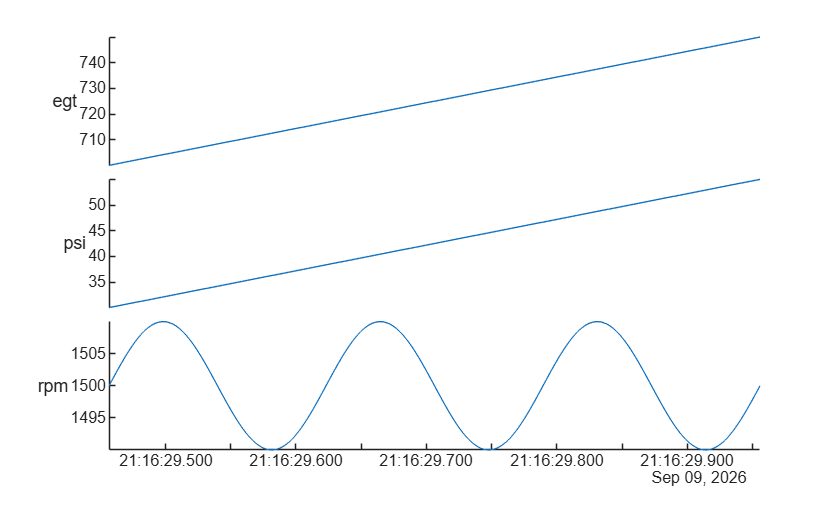

% To plot it, pivot first. These rows are long — one row per channel per
% instant — so value against ts would interleave all three into a sawtooth.
wide = unstack(rowsOut, "value", "channel");
stackedplot(wide.ts, wide{:, 2:end}, ...
            DisplayLabels=wide.Properties.VariableNames(2:end))

% --- done ---------------------------------------------------------------
delete(dataset);
delete(asset);
delete(client);